**Student Name:** Naman Shah

**Last 4 Digits of RUID:** 8939

**Section:** C1

**Math 250 MATALB Assignment:** 2

rand('seed', 8939)

**Question 1**. Solving Ax = b

A = rmat(3, 5), rank(A(:, 1:3))

A =      8     6     6     6     4
     2     5     9     6     7
     1     8     7     4     0


A =      8     6     6     6     4
     2     5     9     6     7
     1     8     7     4     0


ans = 3

% rank is 3 👍
b = rvect(3), R = rref([A b])

b =      4
     1
     9


R =     1.0000         0         0    0.3462    0.4077   -0.2846
         0    1.0000         0   -0.1154   -1.2692    1.9615
         0         0    1.0000    0.6538    1.3923   -0.9154


% reduced row echeleon form of A 
S = R(:,1:5)

S =     1.0000         0         0    0.3462    0.4077
         0    1.0000         0   -0.1154   -1.2692
         0         0    1.0000    0.6538    1.3923


(1)(a)(i) Columns 1, 2 and 3 are the pivot columns of A

(ii) rank of R = 3, rank of A = 3

(iii) nullity of A = 2, x4 and x5 are the free variables

(iv) The equation A**x** = **b **has a solution because we can assign values to x4 and x5 that can enable the equation to hold true for A**x** = **b **

x1 = -0.2846 - 0.4077**x5** - 0.3462**x4**

x2 = 1.9615 + 1.2692x5 + 0.1152x4

x3 = -0.9154 - 1.3923x5 - 0.6538x4

x4 free

x5 free

(1)(b)

c = R(: ,6)

c =    -0.2846
    1.9615
   -0.9154


x = [c; 0; 0]

x =    -0.2846
    1.9615
   -0.9154
         0
         0


(1)(b)(i)    

A*x-b

ans = 1.0e-14 *

   -0.1776
         0
         0


S*x-c

ans =      0
     0
     0


For the first one, for the one of the components I have -0.1776 which is close to zero.

For all others parts of Ax-b and the entire Sx-c, it is zero vector.

(1)(b)(ii)

The property states that if a column contains the leading entry of the same row, then all the other entries of that column are zero. Therefore, Ax-b = Sx-c = 0

(1)(c)

u = [-S(:,4); 1; 0], v = [-S(:,5);0;1]

u =    -0.3462
    0.1154
   -0.6538
    1.0000
         0


v =    -0.4077
    1.2692
   -1.3923
         0
    1.0000


(1)(c)(ii)

In the context of the general solution, u and v are arbitary vectors that span the null space. Hence, u and v, which are random vectors in a sense, will result in zero. 

S*u

ans =      0
     0
     0


A*u

ans = 1.0e-15 *

         0
         0
    0.4441


S*v

ans =      0
     0
     0


A*u

ans = 1.0e-15 *

         0
         0
    0.4441


All the results are approximately zero vectors.

s = rand(1)

s = 0.5775

t = rand(1)

t = 0.9566

y = s*u + t*v

y =    -0.5899
    1.2808
   -1.7095
    0.5775
    0.9566


y

y =    -0.5899
    1.2808
   -1.7095
    0.5775
    0.9566


A*y

ans = 1.0e-14 *

    0.1776
         0
    0.0444


A0 is the m*1 zero vector, so that is zero.

If y is the m × n zero matrix, then Ay is the m × 1 zero vector

Yes, Ay is approximately zero.

(1)(d)

z = x+y

z =    -0.8745
    3.2423
   -2.6248
    0.5775
    0.9566


(2)

A*z

ans =     4.0000
    1.0000
    9.0000


b

b =      4
     1
     9


A*z-b

ans = 1.0e-14 *

         0
         0
    0.1776


We can see that Az = b

The property that ensures that Az=b is A(x+y) = Ax + Ay

And Az-b = 0 by the same logic

## Question 2. Spanning Sets and Linear Independence

u1 = rvect(3)

u1 =      3
     7
     8


u2 = rvect(3)

u2 =      8
     0
     2


u3 = rvect(3)

u3 =      0
     7
     6


u4 = rvect(3)

u4 =      3
     5
     5


(a)

T = {u1, u2, u3}

T = 1×3 cell array
    {3×1 double}    {3×1 double}    {3×1 double}


A = [u1, u2, u3]

A =      3     8     0
     7     0     7
     8     2     6


rref(A)

ans =      1     0     0
     0     1     0
     0     0     1


(i)

Ax = 0, has no free variables

(ii)

The set T is linearly indpedent, becaused the reduced row echeleon of the matrix has all three pivot coluns and no free variables. The matrix is also consistent for all b in **R^3**

(c)

v = rand(1)*u1 + rand(1)*u2

v =     5.8482
    1.7641
    3.2892


v is the form of c1u1 + c2u2  for some scalars c1 and c2

U = {u1, u2, v}

U = 1×3 cell array
    {3×1 double}    {3×1 double}    {3×1 double}


u1

u1 =      3
     7
     8


u2

u2 =      8
     0
     2


v

v =     5.8482
    1.7641
    3.2892


We know u1 and u2 are linearly independent as the set T is linearly independent. But, v can be expressed as a linear combination of the u1 and u2, meaning it is linearly dependent on u1 and u2, making the set U **linearly dependent**

U_but_matrix = [u1, u2, v]

U_but_matrix =     3.0000    8.0000    5.8482
    7.0000         0    1.7641
    8.0000    2.0000    3.2892


rref(U_but_matrix)

ans =     1.0000         0    0.2520
         0    1.0000    0.6365
         0         0         0


As we can see from the RREF of the U_but_matrix, the reduced row of echelon is not consistent if Ux = b in **R^3 **has a non zero component in the third row. This makes the set U linearly dependent.

## Question 3. Matrix Multiplication

A = rmat(2, 3)

A =      8     9     6
     5     2     1


A =      8     9     6
     5     2     1


B = rmat(3, 4)

A =      2     4     3     7
     6     6     2     7
     6     1     8     1


B =      2     4     3     7
     6     6     2     7
     6     1     8     1


C = rmat(4, 3)

A =      6     3     4
     1     6     7
     9     7     8
     8     1     7


C =      6     3     4
     1     6     7
     9     7     8
     8     1     7


v = rvect(4)

v =      8
     6
     9
     4


Matrix Mulitplication of AB

A*B

ans =    106    92    90   125
    28    33    27    50


(1)

(a)

u = B*v

u =     95
   130
   130


A*u

ans =         2710
         865


D = A*B

D =    106    92    90   125
    28    33    27    50


D*v

ans =         2710
         865


Yes Au = A(Bv), is the same as Dv = (AB)v which is [2710; 865]

U = B*C

U =     99    58   109
   116    75   131
   117    81   102


A*U

ans =         2538        1625        2663
         844         521         909


D = A*B

D = 2×4
   106    92    90   125
    28    33    27    50


D*C

ans = 2×3
        2538        1625        2663
         844         521         909


Yes, (AB)C = A(BC)

(b)

A = [0 1; 0 0]

A = 2×2
     0     1
     0     0


B = [0 0; 1 0]

B = 2×2
     0     0
     1     0


C = [0 1; 1 0]

C = 2×2
     0     1
     1     0


(i)

A*B

ans = 2×2
     1     0
     0     0


B*A

ans = 2×2
     0     0
     0     1


No, AB is not equal to BA

(A+B)^2

ans = 2×2
     1     0
     0     1


A^2+B^2+2*A*B

ans = 2×2
     2     0
     0     0


No, (A+B)^2 is not equal to A^2+B^2+2AB

A^2+B^2+A*B+B*A

ans = 2×2
     1     0
     0     1


But, (A+B)^2 = A^2+B^2+AB+BA

(ii)

A

A = 2×2
     0     1
     0     0


A^2

ans = 2×2
     0     0
     0     0


If A was a number let's say 2, A^2 would 2*2 = 4, meaning a value usually bigger than A.

On the other hand for A =  [0 1; 0 0], A^2 is a zero matrix, usually A^2 for numbers aren't zero vectors.

(iii)

A*C

ans = 2×2
     1     0
     0     0


A*B

ans = 2×2
     1     0
     0     0


AC = AB, if these were numbers and A!=0, we could have said that B = C, but as we can see below B = [0 0; 1 0], C = [0 1; 1 0], clearly different.

B

B = 2×2
     0     0
     1     0


C

C = 2×2
     0     1
     1     0


## Question 4. (0, 1) Matrices

A = [ 0 0 0 1 0 1
1 0 1 1 0 0
0 1 0 1 0 0
1 0 1 0 0 0
1 1 1 0 0 1
0 0 1 1 0 0]

A = 6×6
     0     0     0     1     0     1
     1     0     1     1     0     0
     0     1     0     1     0     0
     1     0     1     0     0     0
     1     1     1     0     0     1
     0     0     1     1     0     0


(4)(i)

Image for directed graph

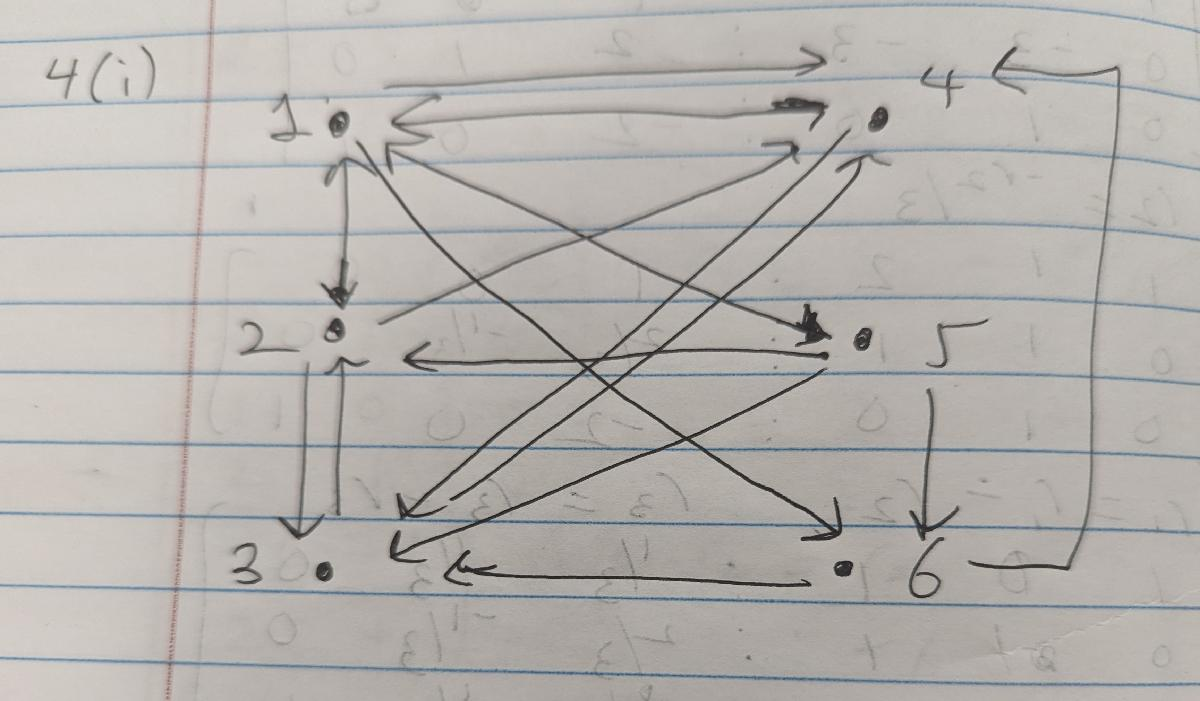

(4)(ii)

On the fifth column of A, it is 5x1 zero vector, so we can that person isn't receiving a message from anyone else

Even from the image, we can see that 5 never receives any messages, but he does send out a lot messages.

A(:, 5)

ans = 6×1
     0
     0
     0
     0
     0
     0


(4)(iii)

A

A = 6×6
     0     0     0     1     0     1
     1     0     1     1     0     0
     0     1     0     1     0     0
     1     0     1     0     0     0
     1     1     1     0     0     1
     0     0     1     1     0     0


A^2

ans = 6×6
     1     0     2     1     0     0
     1     1     1     2     0     1
     2     0     2     1     0     0
     0     1     0     2     0     1
     1     1     2     4     0     1
     1     1     1     1     0     0


A^3

ans = 6×6
     1     2     1     3     0     1
     3     1     4     4     0     1
     1     2     1     4     0     2
     3     0     4     2     0     0
     5     2     6     5     0     1
     2     1     2     3     0     1


A^4

ans = 6×6
     5     1     6     5     0     1
     5     4     6     9     0     3
     6     1     8     6     0     1
     2     4     2     7     0     3
     7     6     8    14     0     5
     4     2     5     6     0     2


In stage 1, Person 1 can send in 1 way

In stage 2, Person 1 can send in 1 way

In stage 3, Person 1 can send in 3 ways

In stage 4, Person 1 can send in 5 ways.

B = A + A^2 + A^3 + A^4

B = 6×6
     7     3     9    10     0     3
    10     6    12    16     0     5
     9     4    11    12     0     3
     6     5     7    11     0     4
    14    10    17    23     0     8
     7     4     9    11     0     3


In a case with atmost 4 cases, person 3 can send a message to person 4 in **12 ways.**